# 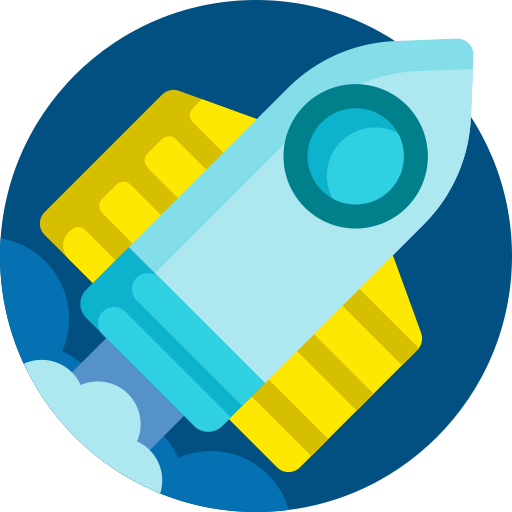

# **MEC3079S: Control Systems**

# Chapter 11 — Transient design specifications

## 11.1 Introduction

We previously introduced three performance metrics when analysing a control system, namely

- transient response,

- stability, and

- steady-state error.

We have now discussed closed-loop stability in detail as part of **Chapter 9**, which allowed us to quantify the level of stability when visualising the frequency response of loop transfer function $L(s)$ in a relevant diagram. In **Chapter 10 **we considered steady-state error specifications, as well as the associated type of loop transfer behaviour required to achieve the particular steady-state specification. While this assures the correct behaviour as time tends to infinity ($t\rightarrow \infty$), or equivalently, when frequency tends to zero ($\omega\rightarrow 0$), it does not consider the transient behavior of the output response. **Chapter 11** will focus on deriving design specifications related to transient performance that can be interpreted in the frequency domain. These frequency-domain design specifications will form the basis of the feedback control design that we will use in **Chapter 12**.

## 11.2 Sensitivity in the frequency domain

### 11.2.1 Design objective

As previously introduced, the sensitivity function is given by

$S(s)=\frac{1}{1+P(s)G(s)}=\frac{1}{1+L(s)}$,

where $L(s)=P(s)G(s)$ is the loop transfer function for a system in unity-feedback as shown in Figure 11.1.

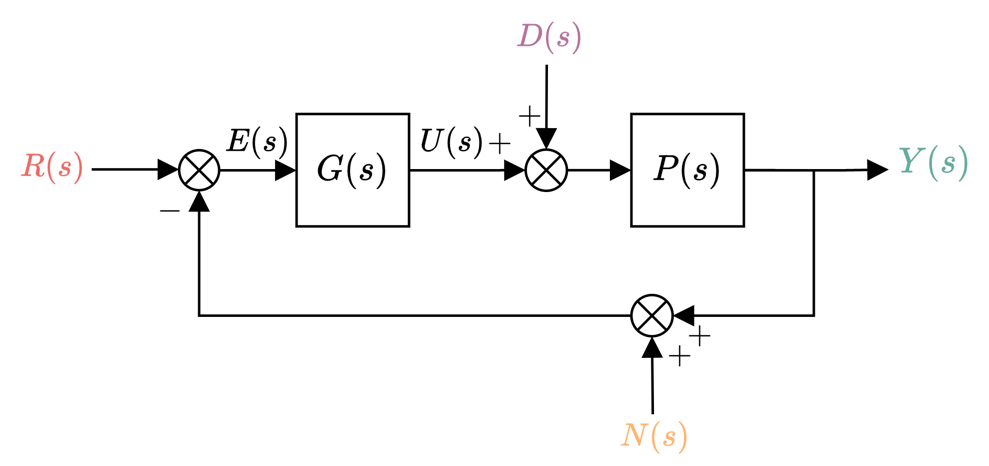

**Figure 11.1**: Block diagram of closed-loop system with external signals acting on it.

With reference to the block diagram, the tracking error is given by

$E(s) = \frac{1}{1+P(s)G(s)}R(s)-\frac{P(s)}{1+P(s)G(s)}D(s)-\frac{1}{1+P(s)G(s)}N(s)$,

where $N(s)$ is zero-mean high-frequency noise, and $D(s)$ is a load disturbance. Based on the equation above, the sensitivity function also represents the transfer behaviour from the reference signal and noise to the tracking error, and is directly proportional to the transfer behaviour from the disturbance to error. In other words, the equation above can be parameterised by the sensitivity function as

$E(s) = S(s)R(s)-PS(s)D(s)-S(s)N(s)$.

If our objective is for the output response $Y(s)$ to match the reference $R(s)$ in some manner, then we are equivalently attempting to make $E(s)=R(s)-Y(s)$ sufficiently small at low frequencies (when $n(t)\approx 0$), as this will make $e(t)=r(t)-y(t)$ small. Based on the equation above, we can do this by making the sensitivity function sufficiently small ($|S(j\omega)|\ll 1$)  at frequencies where we expect $R(s)$ and $D(s)$ to act — usually at low frequencies — so that all expected reference signals can be approximately tracked. Owing to the fact that there will be sensor noise at higher frequencies via $N(s)$, we then make $|S(j\omega)|\approx 1$ for all other frequencies.

Our only means of adjusting the sensitivity function is to adjust $G(s)$, so it would be useful to have a clear picture of how $G(s)$ affects $S(s)$ across all frequencies. 

### 11.2.2 Relationship with stability margin

Recall that the stability margin, $s_M$, is defined as the distance between the critical point and the *closest* point of $L(j\omega)$ when visualised in a Nyquist diagram, as shown in Figure 11.2. 

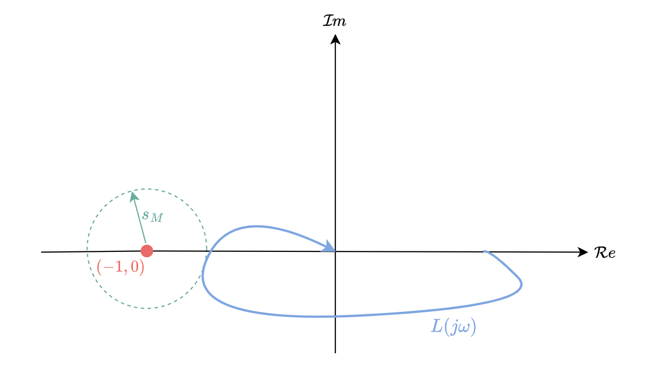

**Figure 11.2**: Graphical representation of stability margin in arithmetic complex plane.

Mathematically, this can be written as

$
s_M 
\leq |1+L(j\omega)|
$,

Which implies that the distance between any point on $L(j\omega)$ and the critical point is always equal to or greater than $s_M$. The stability margin is related to the gain and phase margins in that it gives us an indication of closed-loop stability based on how far away $L(j\omega)$ is from the critical point. If we divide both sides of the equation above by $s_M|1+L(j\omega)|$, we get

$\left| \frac{1}{1+L(j\omega)}\right| \leq \frac{1}{s_M}$,

where the left-hand side of the above equation is now the magnitude response of the sensitivity function, and the right-hand side is the inverse of the stability margin. Making the sensitivity function small at all frequencies will therefore ensure that the stability margin is large based on the relationship above. This means that our objectives to track reference signals and have good stability margins are aligned — both require small sensitivity functions. However, for the purposes of a good stability margin, we only need to make $|S(j\omega)|$ small when in the vicinity of the critical point.

The mathematical relationship above also implies that the maximum value of $\left| S(j\omega)\right|=\left| \frac{1}{1+L(j\omega)}\right| $ will be equal to $\frac{1}{s_M$, namely

 $\left| S(j\omega)\right|_{max}=\frac{1}{s_M}$,

which we can read off from a Bode magnitude response graph of $|S(j\omega)|$ in order to design for or analyse the stability margin.

#### Example

*Determine the stability margin from the Bode magnitude response of the sensitivity function when *$L(s)=\frac{5}{s(s+1)}$.

clear
s = tf('s');

L = 5/s/(s+1)


L =
 
     5
  -------
  s^2 + s
 
Continuous-time transfer function.
Model Properties


S = 1/(1+L)


S =
 
    s^2 + s
  -----------
  s^2 + s + 5
 
Continuous-time transfer function.
Model Properties


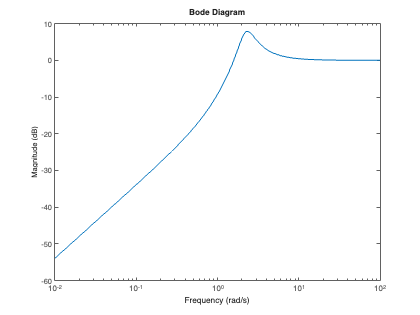


figure, hold on
bodemag(S)
yline(9.62,'--','$9.62$ dB','Interpreter','latex')

magS_max = 10^(7.93/20)

magS_max = 2.4917

The maximum value of the sensitivity function is found to be 

$20\log_{10}|S(j\omega)|_{max}\approx 7.93$ dB,

or $\left| S(j\omega)\right|_{max}\approx 2.49$ in arithmetic units. The stability margin can then be determined as

 $s_M=\frac{1}{\left| S(j\omega)\right|_{max}}=\frac{1}{2.49}=0.4$.

### 11.2.3 Sensitivity M circles in the complex plane

The previous section has shown that there is a relationship between circles originating at the critical point and the magnitude response of the sensitivity. Following from this, if we want to determine if the magnitude response of the sensitivity function is ever equal to some value $M$, namely

$\left| \frac{1}{1+L(j\omega)}\right| = M$,

then we can draw a circle centred on the critical point, with radius $\frac{1}{M}$, and if $L(j\omega)$ intersects this circle, then $S(j\omega)$ will have a magnitude response of $M$ at the frequency corresponding to the intersection. However, if $L(j\omega)$ never intersects the circle, then $S(j\omega)$ never has a magnitude response of $M$.

The code below generates sensitivity $M$ circles for $M \in \{0.5,1,2\}$.

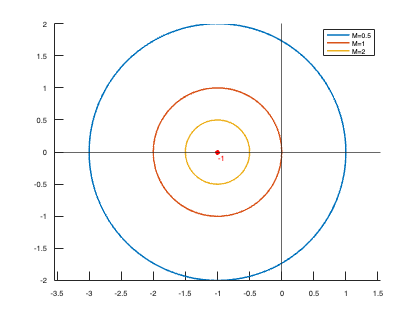

clear

M_array=[0.5 1 2];
the = (0:1:360)*pi/180;

figure, hold on
for M=M_array
    circ = -1+1/M*exp(1i*the);
    plot(real(circ),imag(circ),'-',lineWidth=2)
end
plot(-1,0,'ro',MarkerFaceColor='r')
text(-1,-.1,'-1','Color','r')
xline(0,'-'),yline(0,'-')
legend('M=0.5','M=1','M=2')
axis equal

#### Example

*Using the Nyquist diagram, determine whether the sensitivity function ever has a gain that exceeds *$M=1.5$* when *$L(s)=\frac{1}{s(s+0.8)}$*.*

The code below generates the locus of $L(j\omega)$, as well as sensitivity $M$ circles, which have a corresponding radius of $\frac{1}{M}$.

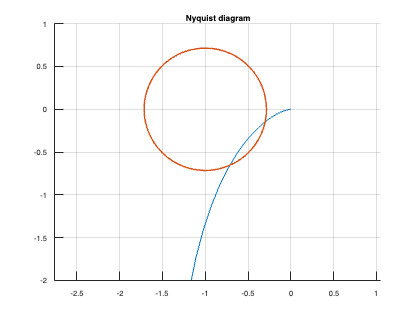

clear
s = tf('s');
L = 1/s/(s+0.8);
[re,im] = nyquist(L);

figure, hold on, grid on
plot(squeeze(re),squeeze(im))

the = (0:1:360)*pi/180;
M = 1.4;
circ = -1+1/M*exp(1i*the);
plot(real(circ),imag(circ),'-',lineWidth=2)

xlim([-2,1]),ylim([-2,1])
title('Nyquist diagram')
axis equal

When $M=1.5$, resulting in a circle with radius of $r=\frac{1}{M}=\frac{2}{3}$, the $L(j\omega)$ locus does intersect the circle, which means that the sensitivity is larger than $M=1.5$ for a range of frequencies (when the locus resides within the $M=1.5$ circle). If we increase the value of $M$ using the code above, we will see that eventually $L(j\omega)$ will not intersect the resulting circle, which will represent the maximum gain of the sensitivity function.

We can plot the Bode magnitude response of $S(s)=\frac{1}{1+L(s)}$ using the code below.

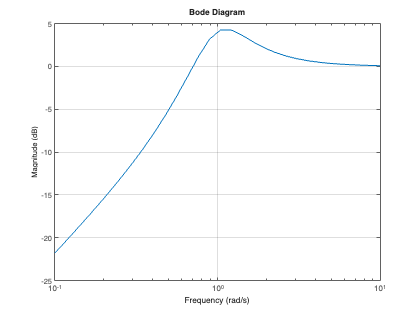

S = 1/(1+L);

figure, hold on
bodemag(S)
yline(20*log10(M),'--k',['$M_{dB}=20\log$', num2str(M),'$\approx$',num2str(20*log10(M),2)],'Interpreter','latex')
grid on

As expected, the sensitivity function has a gain that exceeds $1.5$.

### 11.2.3 The inverse Nichols chart

We can also represent the sensitivity $M$ circle boundaries in the log-polar plane as follows. Rearranging

$\left| \frac{1}{1+L(j\omega)}\right|= \frac{1}{\left|1+L(j\omega)\right|} = M$,

we can can define the relationship of

$|L(j\omega)+1|=\frac{1}{M}$.

As before, the equation above represents a circle, centred at $c=-1$ (the critical point in the complex plane), with a radius of $r=\frac{1}{M}$, which gives us an equivalent representation of 

$|L(j\omega)-c|=r$.

We can then solve for $L(j\omega)$ as


$$\begin{array}{rl}
L(j\omega)
&=c+re^{j\phi},\\
&=-1+\frac{1}{M}e^{j\phi},
\end{array}$$


where $\phi\in \left[0,2\pi\right]$ is a parameter that we must sweep through in order to draw the circle that describes all solutions of $|L(j\omega)+1|=\frac{1}{M}$. The log-polar plot requires determining magnitude response (in dB) and phase angle (in degrees) or $L(j\omega)$, which we then determine using

$\begin{array}{rl}
|L(j\omega)|_{dB}
&=20\log_{10}\left|-1+\frac{1}{M}e^{j\phi}\right|
\end{array}$,

and

$\begin{array}{rl}
\angle L(j\omega)
&=\angle \{-1+\frac{1}{M}e^{j\phi}\}\frac{180}{\pi}
\end{array}$.

The code block below generates the resulting grid lines in the log-polar plot for a range of $M$ values.

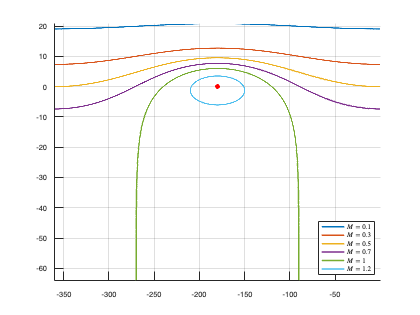

clear
M_array=[0.1 0.3 0.5 .7 1 2];

figure, hold on
for M=M_array

    phi = linspace(0,2*pi,1e4);
    c = -1;
    r = 1/M;
    L = c + r*exp(1i*phi);

    mag_L = 20*log10( abs(L) );
    phi_L = angle( L )*180/pi;
    for i=1:length(phi_L)
        if( phi_L(i) > 0), phi_L(i) = phi_L(i)-360; end
    end
    
    plot( phi_L(2:end-1),mag_L(2:end-1),LineWidth=2 )
end
plot(-180,0,'ro',MarkerFaceColor='r')
legend('$M=0.1$','$M=0.3$','$M=0.5$','$M=0.7$','$M=1$','$M=1.2$','Interpreter','latex',Location='southeast')
axis tight
grid on

What we should first notice is that $M$ circles in the complex plane map to warped boundaries in the log-polar plane. We can still imagine them as "closed shapes", where the resulting grid lines that span the entire phase range close off entire regions below them. We also see that as the $M$ values increase, the boundaried regions shrink and approach the critical point (represented with a red dot), as was the case with the $M$ circles in the complex plane. When grid lines corresponding to the magnitude response of $S(j\omega)$ are overlaid in the log-polar plane, we refer to this type of plot as an **inverse Nichols chart**.

Assuming we can generate these grid lines in the log-polar plane, we can then make assertions about the magnitude response of $S(j\omega)$ when the response of $L(j\omega)$ is also present in the log-polar plane.

#### Example

*Using the inverse Nicholas chart, determine whether the sensitivity function ever has a gain that exceeds *$M=1.5$* when *$L(s)=\frac{1}{s(s+0.8)}$*.*

Note that this is the same example as before. The code below generates the locus of $L(j\omega)$, as well as grid lines for the warped sensitivity $M$ circles.

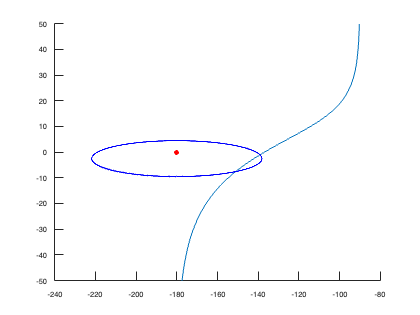

clear
s = tf('s');
Ls = 1/s/(s+0.8);

M = 1.5;

phi = linspace(0,2*pi,1e4);
c = -1;
r = 1/M;
L = c + r*exp(1i*phi);

mag_L = 20*log10( abs(L) );
phi_L = angle( L )*180/pi;
for i=1:length(phi_L)
    if( phi_L(i) > 0), phi_L(i) = phi_L(i)-360; end
end

figure, hold on
[magL,phiL] = nichols(Ls,{1e-3,1e3});
plot(squeeze(phiL),squeeze(20*log10(magL)))

plot( phi_L(2:end-1),mag_L(2:end-1),'-b',LineWidth=2 )
plot(-180,0,'ro',MarkerFaceColor='r')

ylim([-50,50])

The $L(j\omega)$ locus is shown to intersect the $M=1.5$ grid line (matching our previous assessment), which means that the sensitivity function will have a magnitude response that exceeds $1.5$ for frequencies that place $L(j\omega)$ within the contour. We can also see that increasing the $M$ value sufficiently will eventually result in no intersection, which means that our sensitivity gain is limited, as shown in the corresponding Bode magnitude response below.

S = 1/(1+Ls);

figure, hold on
bodemag(S)
yline(20*log10(M),'-b',['$M_{dB}=20\log$', num2str(M),'$\approx$',num2str(20*log10(M),2)],'Interpreter','latex','LineWidth',2)
grid on

ylim([-25 15])

## 11.3 Complementary sensitivity in the frequency domain

### 11.3.1 Design objective

As the name implies, the sensitivity function and complementary sensitivity functions are related by

$S(s)+T(s)=1$,

where the complementary sensitivity function is defined as

$T(s)=\frac{L(s)}{1+L(s)}$.

Recall, with reference to the block diagram in Figure 11.3, that the output response is related to all exogenous signals by


$$\begin{array}{rl}
Y(s) 
&= \frac{P(s)G(s)}{1+P(s)G(s)}R(s)+\frac{P(s)}{1+P(s)G(s)}D(s)-\frac{P(s)G(s)}{1+P(s)G(s)}N(s),\\
&= T(s)R(s)+PS(s)D(s)-T(s)N(s),\\
\end{array}$$


where the complementary sensitivity function describes the mapping from reference $R(s)$ and noise $N(s)$ to the output $Y(s)$.

**Figure 11.3**: Block diagram of closed-loop system with exogenous signals.

As previously discussed, we would like to make $|T(j\omega)|\approx 1$for the low-frequency range where we expect $R(s)$ to act, as this will give us good reference tracking for sufficiently low-frequency reference signals. We then want to make $|T(j\omega)|\ll 1$for the high-frequency range where we expect high-frequency noise term $N(s)$ to act, in order to avoid noise making its way to the output of our system. An idealised Bode magnitude response of the complementary sensitivity function is shown in Figure 11.4.

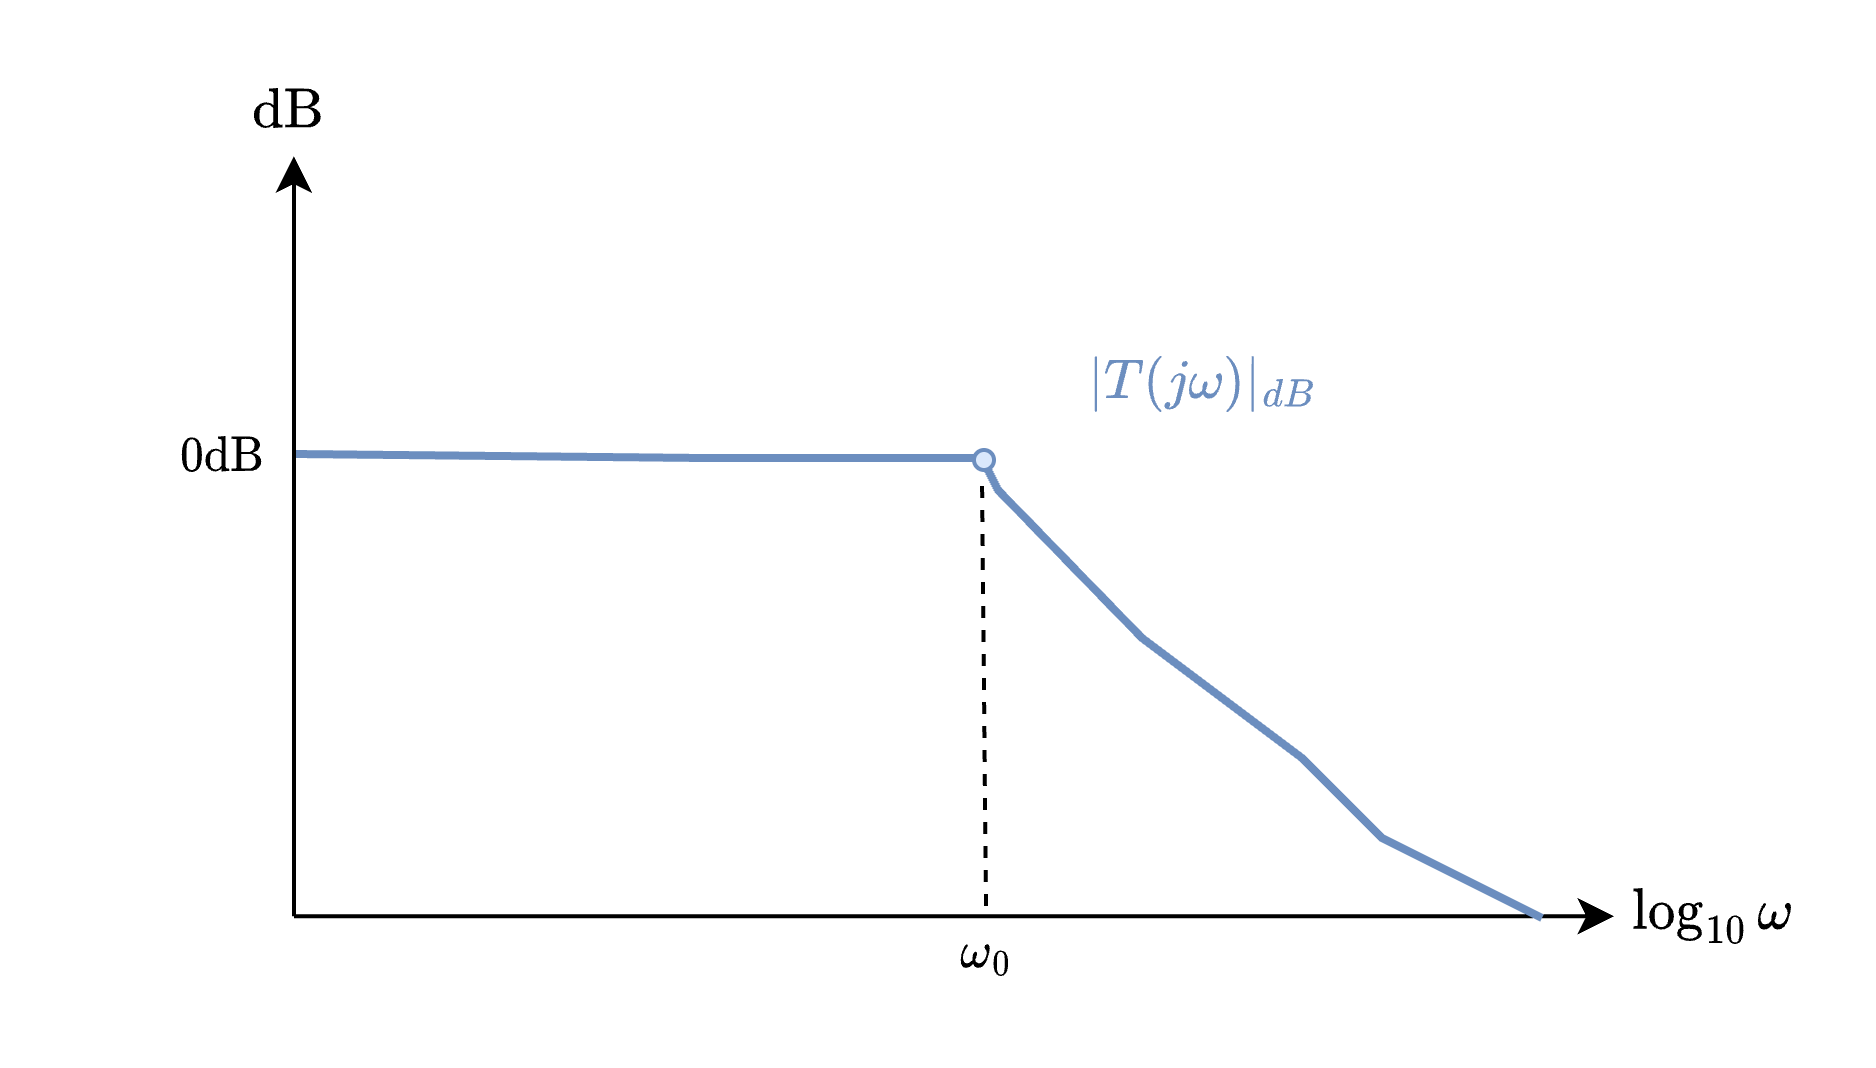

**Figure 11.4**: Idealised Bode magnitude response of complementary sensitivity function.

Given that we only have agency over the structure of $G(s)$, we therefore want to adjust $L(s)=P(s)G(s)$ in order to shape the behaviour of $T(s)$ as required. In order to do this, we need to be able to define design specifications on $L(s)$ that relate directly to design specifications on $T(s)=\frac{L(s)}{1+L(s)}$. With this in place, we can then adjust $L(s)$ using $G(s)$, based on the design requirements of $T(s)$, such as bandwidth, overshoot, and steady-state error.

### 11.3.2 The Nichols chart

Similar to the sensitivity $M$ circles that we used previously to describe the sensitivity magnitude response, we can assign a complementary sensitivity $M$ circle as

$|T(j\omega)|=\left|\frac{L(j\omega)}{1+L(j\omega)}\right|=M$. 

If we now divide the numerator and denominator of $|T(j\omega)|$ by $L(j\omega)$ we obtain

$\left|\frac{1}{1/L(j\omega)+1}\right|=M$. 

We can then make a variable substitution of 

$K(j\omega)=\frac{1}{L(j\omega)}$,

which results in 

$\left|\frac{1}{K(j\omega)+1}\right|=M$. 

With reference to **Section 11.2.3**, the above equation has the form of a sensitivity function, albeit with $K(j\omega)$ instead of $L(j\omega)$. We can therefore use our results from the previous section to solve the above equation for $K(j\omega)$, namely

$\begin{array}{rl}
|K(j\omega)|_{dB}
&=20\log_{10}\left|-1+\frac{1}{M}e^{j\phi}\right|
\end{array}$,

and

$\begin{array}{rl}
\angle K(j\omega)
&=\angle \{-1+\frac{1}{M}e^{j\phi}\}\frac{180}{\pi}
\end{array}$.

If we were to plot this information in the log-polar plane, we would end up with the same grid lines as before. However we are interested in plotting the grid lines of $L(j\omega)$ resulting from $|T(j\omega)|=\left|\frac{L(j\omega)}{1+L(j\omega)}\right|=M$. Noting that $K(j\omega)=\frac{1}{L(j\omega)}$, the magnitude response relationship will therefore be

$|K(j\omega)|_{dB}=-|L(j\omega)|_{dB}$,

and the phase response relationship will be

$\angle K(j\omega)=-\angle L(j\omega)$.

In other words, once we have determined the (logarithmic) magnitude and phase response of $K(j\omega)$ and have plotted them in the log-polar plane (which would look like sensitivity grid lines), we then need to turn our log-polar plot "upside down", which switches the logarithmic gain and phase as per the equations above. In fact, because the grid lines resulting from sensitivity $M$ circles are symmetric about the $-180^\circ$ phase line in the log-polar plane, we really just need to reflect our sensitivity grid lines about the $0$ dB x-axis in order to obtain complementary sensitivity grid lines.

The code block below generates the resulting grid lines in the log-polar plot for a range of $M$ values.

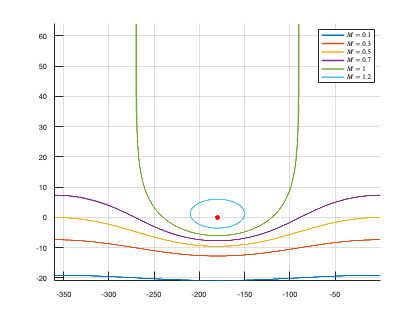

clear
M_array=[0.1 0.3 0.5 .7 1 2];

figure, hold on
for M=M_array

    phi = linspace(0,2*pi,1e4);
    c = -1;
    r = 1/M;
    K = c + r*exp(1i*phi);

    mag_K = 20*log10( abs(K) );
    phi_K = angle( K )*180/pi;
    for i=1:length(phi_K)
        if( phi_K(i) > 0), phi_K(i) = phi_K(i)-360; end
    end
    
    plot( phi_K(2:end-1),-mag_K(2:end-1),LineWidth=2 )
end
plot(-180,0,'ro',MarkerFaceColor='r')
legend('$M=0.1$','$M=0.3$','$M=0.5$','$M=0.7$','$M=1$','$M=1.2$','Interpreter','latex')
axis tight
grid on

Note that these grid lines are equivalent to sensitivity grid lines that have been reflected about the $0$dB x-axis. We can therefore plot $L(j\omega)$ on a log-polar plot and then have a way to determine what the corresponding $|T(j\omega)|$ will be based on when $L(j\omega)$ intersects a particular grid line. When displaying the grid lines of the complementary sensitivity magnitude response on a log-polar plot, we refer to this as a **Nichols chart**.

#### Example

*Using the Nicholas chart, determine whether the complementary sensitivity function ever has a gain that exceeds *$M=1.5$* when *$L(s)=\frac{1}{s(s+0.8)}$*.*

The code below generates the locus of $L(j\omega)$, as well as grid lines for the warped complementary sensitivity $M$ circles.

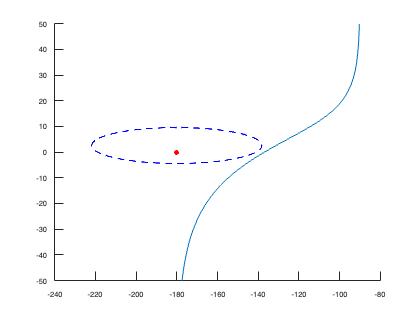

clear
s = tf('s');
L = 1/s/(s+0.8);

M = 1.5;

phi = linspace(0,2*pi,1e4);
c = -1;
r = 1/M;
K = c + r*exp(1i*phi);

mag_K = 20*log10( abs(K) );
phi_K = angle( K )*180/pi;
for i=1:length(phi_K)
    if( phi_K(i) > 0), phi_K(i) = phi_K(i)-360; end
end

figure, hold on
[magL,phiL] = nichols(L,{1e-3,1e3});
plot(squeeze(phiL),squeeze(20*log10(magL)))

plot( phi_K(2:end-1),-mag_K(2:end-1),'--b',LineWidth=2 )
plot(-180,0,'ro',MarkerFaceColor='r')

ylim([-50,50])

The $L(j\omega)$ locus is shown to not intersect the $M=1.5$ grid line, which means that the complementary sensitivity function will never have a magnitude response that exceeds $1.5$. The Bode magnitude response of $T(s)$ confirms our answer.

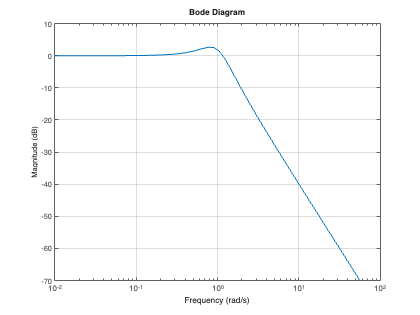

T = L/(1+L);

figure, hold on
bodemag(T)
yline(20*log10(M),'--b',['$M_{dB}=20\log$', num2str(M),'$\approx$',num2str(20*log10(M),2)],'Interpreter','latex','LineWidth',2)
grid on

When using MATLAB's `nichols `function in conjunction with the `grid on` command, MATLAB automatically generates the Nichols chart, albeit with complementary sensitivity $M$circles in decibels. Complementary sensitivity phase lines are also generated, but we will not focus on this for this course. An example is shown using the code below.

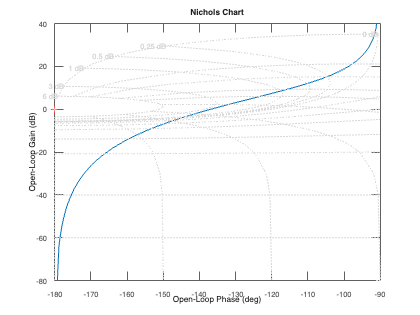

figure
nichols(L)
grid on

## 11.4 Closed-loop design specifications

We have now developed a means of determining the magnitude response of $S(j\omega)$ or $T(j\omega)$ based on visualisation of $L(j\omega)$ in a log-polar plot. The next step is to understand how to convert user specifications into design specifications on the closed-loop system. If we can place design constraints on $T(j\omega)$ or $S(j\omega)$, we can then convert it to design constraints on $L(j\omega)$, as before.

### 11.4.1 Degree of closed-loop systems

While we do not yet possess the tools to manipulate $L(s)$ in a sensible way, we will eventually do so in order to shape $T(s)$ or $S(s)$. An important thing to be aware of is that the order of $L(s)$ will dictate the order of $T(s)$ and $S(s)$. If the loop transfer function is given by

$L(s)=\frac{N(s)}{D(s)}=\frac{a_0+a_1s+a_2s^2+...+a_ms^m}{b_0+b_1s+b_2s^2+...+b_ns^n}$,

where $n\geq m$, then 

$T(s)=\frac{L(s)}{1+L(s)}=\frac{N(s)/D(s)}{1+N(s)/D(s)}=\frac{N(s)}{N(s)+D(s)}$,

and

$S(s)=\frac{1}{1+L(s)}=\frac{1}{1+N(s)/D(s)}=\frac{D(s)}{N(s)+D(s)}$.

So the order of $N(s)+D(s)$, which is the denominator polynomial of $S(s)$ and $T(s)$, will always be less than or equal to the order of $D(s)$, depending on whether there are cancellations in $N(s)+D(s)$. This means that if we know what order $L(s)$ will take, we can then expect equivalent order from $T(s)$ and $S(s)$.

### 11.4.2 User specifications

**User specifications** are often given as high-level closed-loop objectives. This can include various system parameters that we have already considered, such as:

- steady-state error

- maximum percentage overshoot

- peak time

- settling time

- gain margin and phase

- stability margin

- closed-loop bandwidth

Specifications (5)-(7) are easy to determine in the frequency domain and have already been covered in some detail, whereas (2)-(4) are time-domain specifications that must be suitably represented in the frequency domain. Specification (1) is also a time-domain specification, but we have already shown that we can interpret steady-state error in the frequency domain by consulting the low-frequency behaviour of $|L(j\omega)|$.

### 11.4.3 Controller synthesis for first-order systems

Assuming our plant is first-order and strictly proper, namely

$P(s)=\frac{a_0}{b_0+b_1s}$,

and we intend to design a proportional controller of the form $G(s)=K$, then $L(s)=P(s)G(s)$ will also be a first-order system, given by

$L(s)=K\frac{a_0}{b_0+b_1s}$.

The corresponding complementary sensitivity function will follow as a first-order system:

$T(s)=\frac{L(s)}{1+L(s)}=\frac{Ka_0}{Ka_0+b_0+b_1s}$.

Under these conditions, we can specify a desired closed-loop reference model, $M(s)$, which captures the user specifications for the reference to output transfer behaviour. First-order systems are known to not exhibit percentage overshoot, so we are only concerned with settling time and steady-state error. Rewriting $T(s)$ in its canonical form gives

$T(s)=\frac{Ka_0}{Ka_0+b_0+b_1s}=\frac{A_s}{1+sT_c}$,

where

$A_s=\frac{Ka_0}{Ka_0+b_0)}$, 

and

$T_c = \frac{b_1}{Ka_0+b_0}$.

Remembering that the settling time of a first-order system is given by $T_s\approx 4T_c$, we can then ensure that our closed-loop first-order system will be sufficiently fast if 

$4\frac{b_1}{Ka_0+b_0}\leq T_s$,

where $T_s$ is a user specification and $K$ is the only free parameter. Additionally, if a steady-state error percentage is prescribed, given by

$\frac{e(\infty)}{r(\infty)}=\frac{r(\infty)-y(\infty)}{r(\infty)}\leq \beta$,

then noting that $y(\infty)=A_sr(\infty)$, the equation above reduces to

$\frac{e(\infty)}{r(\infty)}=\frac{r(\infty)-y(\infty)}{r(\infty)}=\frac{r(\infty)-A_sr(\infty)}{r(\infty)}=1-A_s\leq \beta$,

and hence

$A_s=\frac{Ka_0}{Ka_0+b_0}\geq 1-\beta$.

Alternatively, if the desired steady-state performance is given relative to a unit step, then we can use final-value theorem, namely

$e(\infty)=\lim_{s\rightarrow 0}sE(s)=\lim_{s\rightarrow 0}\frac{b_0+b_1s}{Ka_0+b_0+b_1s}=\frac{b_0}{Ka_0+b_0}$.

The two constraints on $K$ can be solved individually, and then the intersection of the two solution spaces will describe the admissible $K$ values. For sake of reducing the size of the control action, we often then choose the smallest viable $K$ value.

#### Example

*Synthesize a proportional controller of the form *$G(s)=K$*, which results in a settling time of *$T_s\leq 10$* seconds, with a steady-state error of *$e(\infty)\leq 0.1$ for unit step reference signal*, for the system *$P(s)=\frac{2}{1+2s}$*.*

For the settling time constraint, we require that

$4\frac{b_1}{Ka_0+b_0}=4\frac{2}{2K+1}\leq 10$,

which results in $K\geq -0.1$. For the steady-state error specification, we require that

$\frac{b_0}{Ka_0+b_0}=\frac{1}{2K+1}\leq 0.1$,

which gives $K\geq 4.5$. The intersection of solution spaces for the feedback controller gain is $K\geq 4.5$.

The step response of the closed-loop system is generated using the code below, which shows that the closed-loop system adheres to both constaints.

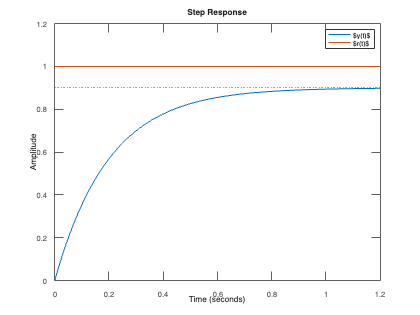

clear
s = tf('s');

P = 2/(1+2*s);
K = 4.5;
L = P*K;
T = feedback(L,1);

figure,hold on
step(T)
step(1+0*s)
ylim([0 1.2])
legend('$y(t)$','$r(t)$','Interpreter','latex')

For values of $K\leq 4.5$, the steady-state error will not be met. Note that because we only have a single parameter, $K$, to vary, we cannot in general meet both the settling time and steady-state error requirements at equality. Instead, there will be overdesign for one of the two specifications.

### 11.4.4 Second-order reference models

#### Setpoint tracking

Assuming $L(s)$ is at least second-order and the focus of the design is setpoint tracking, the design specifications of $T(s)$ can be suitably approximated by a $2^{nd}$-order low-pass filter reference model of the form

$M_R(s)=\frac{\omega_n^2}{s^2+2\zeta\omega_ns+\omega_n^2}$.

Note that the DC gain of $M_R(s)$ is chose as one, which means that step reference signals will be tracked with zero error at steady-state. 

If overshoot and settling time specifications are prescribed for the closed-loop system, then the corresponding $2^{nd}$-order frequency response magnitudes can be used to bound $|T(j\omega)|$.

Recall that the damping ratio of a second-order low-pass filter can be determined from the percentage overshoot specification by 

$\zeta=\frac{-\ln(\%OS/100)}{\sqrt{\pi^2+\ln^2(\%OS/100)}$.

Additionally, the settling time is given by

$T_s=\frac{-\ln\left(0.02\sqrt{1-\zeta^2}\right)}{\zeta\omega_n}\approx \frac{4}{\zeta\omega_n}$,

which allows for determination of $\omega_n$ if $T_s$ and $\zeta$ are known. Based on this, if the desired percentage overshoot and settling time specifications are

$\%OS\leq\alpha$,

$T_s\leq \beta$,

then one can use the above formulas to determine $M_A(s)$. Ideally we could simply set $T(s)=M_R(s)$ and then solve for $G(s)$, but $T(s)$ will, in general, have a different structure to $M_R(s)$, such as when there are more than two poles, or at least one zero. Instead, we can use our reference model to bound $|T(j\omega)|$, namely

$|T(j\omega)|\leq |M_R(j\omega)|$.

#### Disturbance rejection

Assuming $L(s)$ is at least second-order and the focus of the design is disturbance rejection (regulation), the load sensitivity, $P(s)S(s)$, can be suitably approximated by a $2^{nd}$-order band-pass filter reference model of the form


$$M_D(s)=\frac{2k\zeta\omega_ns}{s^2+2\zeta\omega_ns+\omega_n^2},$$


where $\{k,\zeta\,\omega_n\}$ collectively describe the idealised disturbance rejection ability of the closed-loop system. The damping ratio is often chosen to be $\zeta=0.7071$to give an optimally damped response. The value of $k$ can then be determined based on the maximum allowed time-domain peak response equation:


$$y_{p}={2k\zeta}e^{\frac{-\zeta\cos^{-1}\zeta}{\sqrt{1-\zeta^2}}},$$


which yields


$$k=\frac{y_{p}}{2\zeta}e^{\frac{\zeta\cos^{-1}\zeta}{\sqrt{1-\zeta^2}}}.$$


As with the reference tracking approach, the settling time is given by


$$T_s=\frac{-\ln\left(0.02\sqrt{1-\zeta^2}\right)}{\zeta\omega_n}\approx \frac{4}{\zeta\omega_n},$$


which allows for the determination of $\omega_n$ if $T_s$ and $\zeta$ are known/specified. Based on this, if the desired peak response and settling time specifications are

$y_p\leq\alpha$,

$T_s\leq \beta$,

then one can use the above formulas to determine $M_D(s)$. Ideally we could simply set $P(s)S(s)=M_D(s)$ and then solve for $G(s)$, but $P(s)S(s)$ will, in general, have a different structure to $M_D(s)$. Instead, we can use our disturbance rejection reference model to bound $|P(j\omega)S(j\omega)|$, namely


$$|P(j\omega)S(j\omega))|\leq |M_D(j\omega)|.$$


#### Example

*Determine a 2nd-order tracking reference model that represents a system with a settling time of 5 seconds, percentage overshoot of *$25$*%, zero steady-state error for step inputs*

Using the relevant formulas, we can determine the required damping ratio and natural frequency as

$\zeta=\frac{-\ln(\%OS/100)}{\sqrt{\pi^2+\ln^2(\%OS/100)}}=0.40$,

$\omega_n=\frac{4}{\zeta T_s}=1.98$.

The reference model follows as

$M_A(s)=\frac{3.93}{s^2+1.6s+3.93}$.

The code below generates the Bode magnitude response and step response of the reference model.

clear

OS = 25;
Ts = 5;

zeta = -log(OS/100)/sqrt( pi^2+log(OS/100)^2)

zeta = 0.4037

wn = 4/zeta/Ts

wn = 1.9816


Ma = 1/(2*zeta*sqrt(1-zeta*zeta))

Ma = 1.3537


s = tf('s');
M = wn^2/( s^2+2*zeta*wn*s+wn^2)


M =
 
         3.927
  -------------------
  s^2 + 1.6 s + 3.927
 
Continuous-time transfer function.
Model Properties


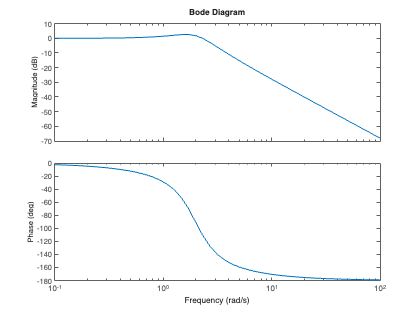




figure, clf
bode(M)

[Gm,Pm,Wcg,Wcp] = margin(M)

Gm = Inf

Pm = 69.6311

Wcg = Inf

Wcp = 2.3008

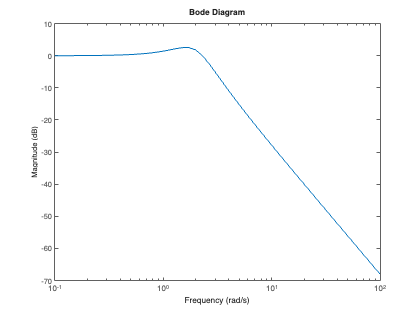



figure
bodemag(M)

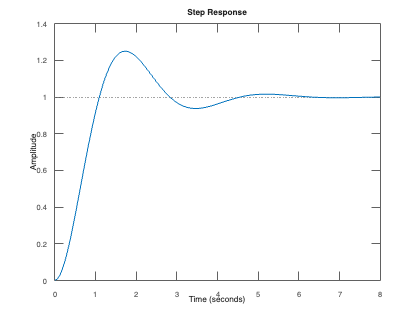

figure
step(M)

## 11.5 Setpoint tracking bounds

As alluded to in the previous section, obtaining an idealised reference model is not sufficient to synthesize an appropriate feedback controller.

### 11.5.1 Above and below tracking bounds

If $T(s)$ is designed such that $|T(j\omega)|\leq |M_R(j\omega)|$ is adhered to, then we have some assurance that our closed-loop system will adhere to the overshoot specification. However, the settling time constraint is not strictly enforced, as there is nothing preventing $T(s)$ having a infinitesimally small magnitude response. To prevent this from happening, we also place a lower bound on the gain of $T(s)$, which results in 

$|M_B(j\omega)|\leq|T(j\omega)|\leq |M_A(j\omega)|$,

where $|M_B(j\omega)|$ represents the *stay-above *bound on $|T(j\omega)|$, and $|M_A(j\omega)|=|M_R(j\omega)|$ represents the *stay-below* bound, as shown in Figure 11.5.

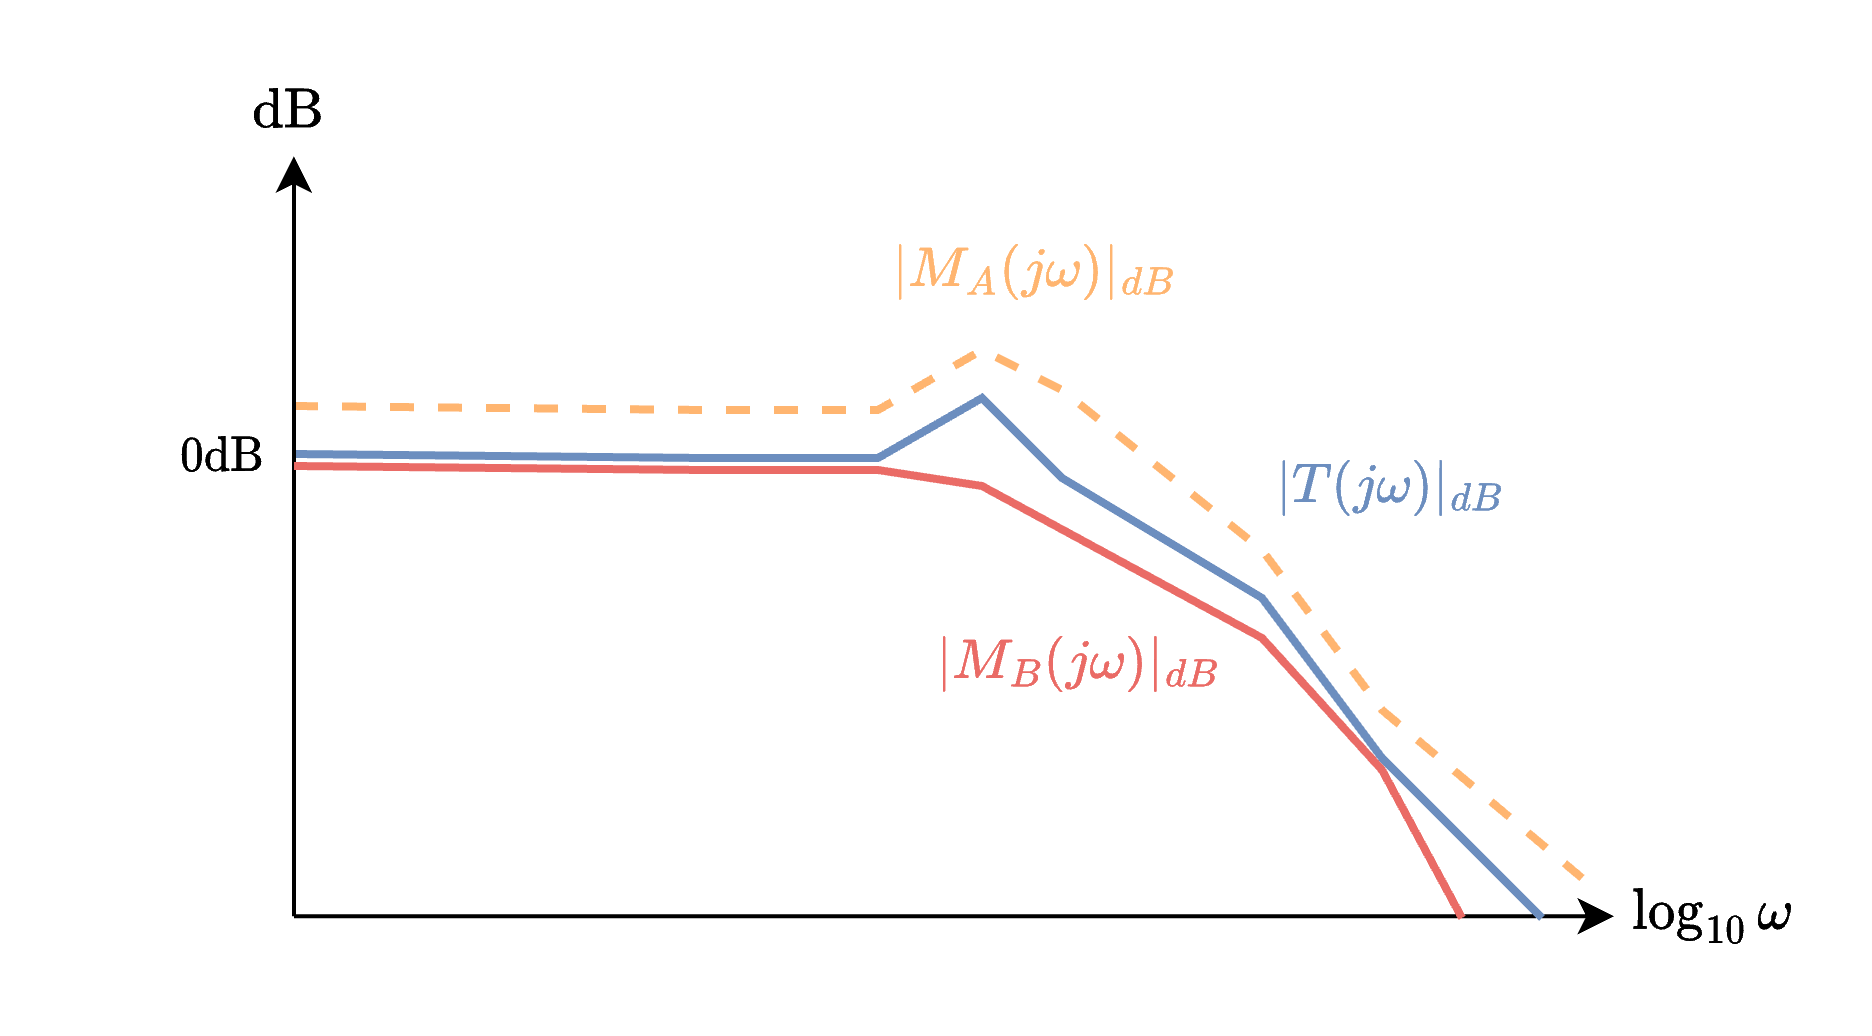

**Figure 11.5**: *Stay-above* and *stay-below* bounds for the magnitude response of $T(j\omega)$.

A valid design of $T(s)$ requires locating $|T(j\omega)|$ within the band made up by $|M_A(j\omega)|$ and $|M_B(j\omega)|$. 

To simplify things, we will consider simplified above and below bounds on $|T(j\omega)|$. Specifically, we will employ a *stay-below* bound for the percentage overshoot specification, and a *stay-above *bound for the settling time specification.

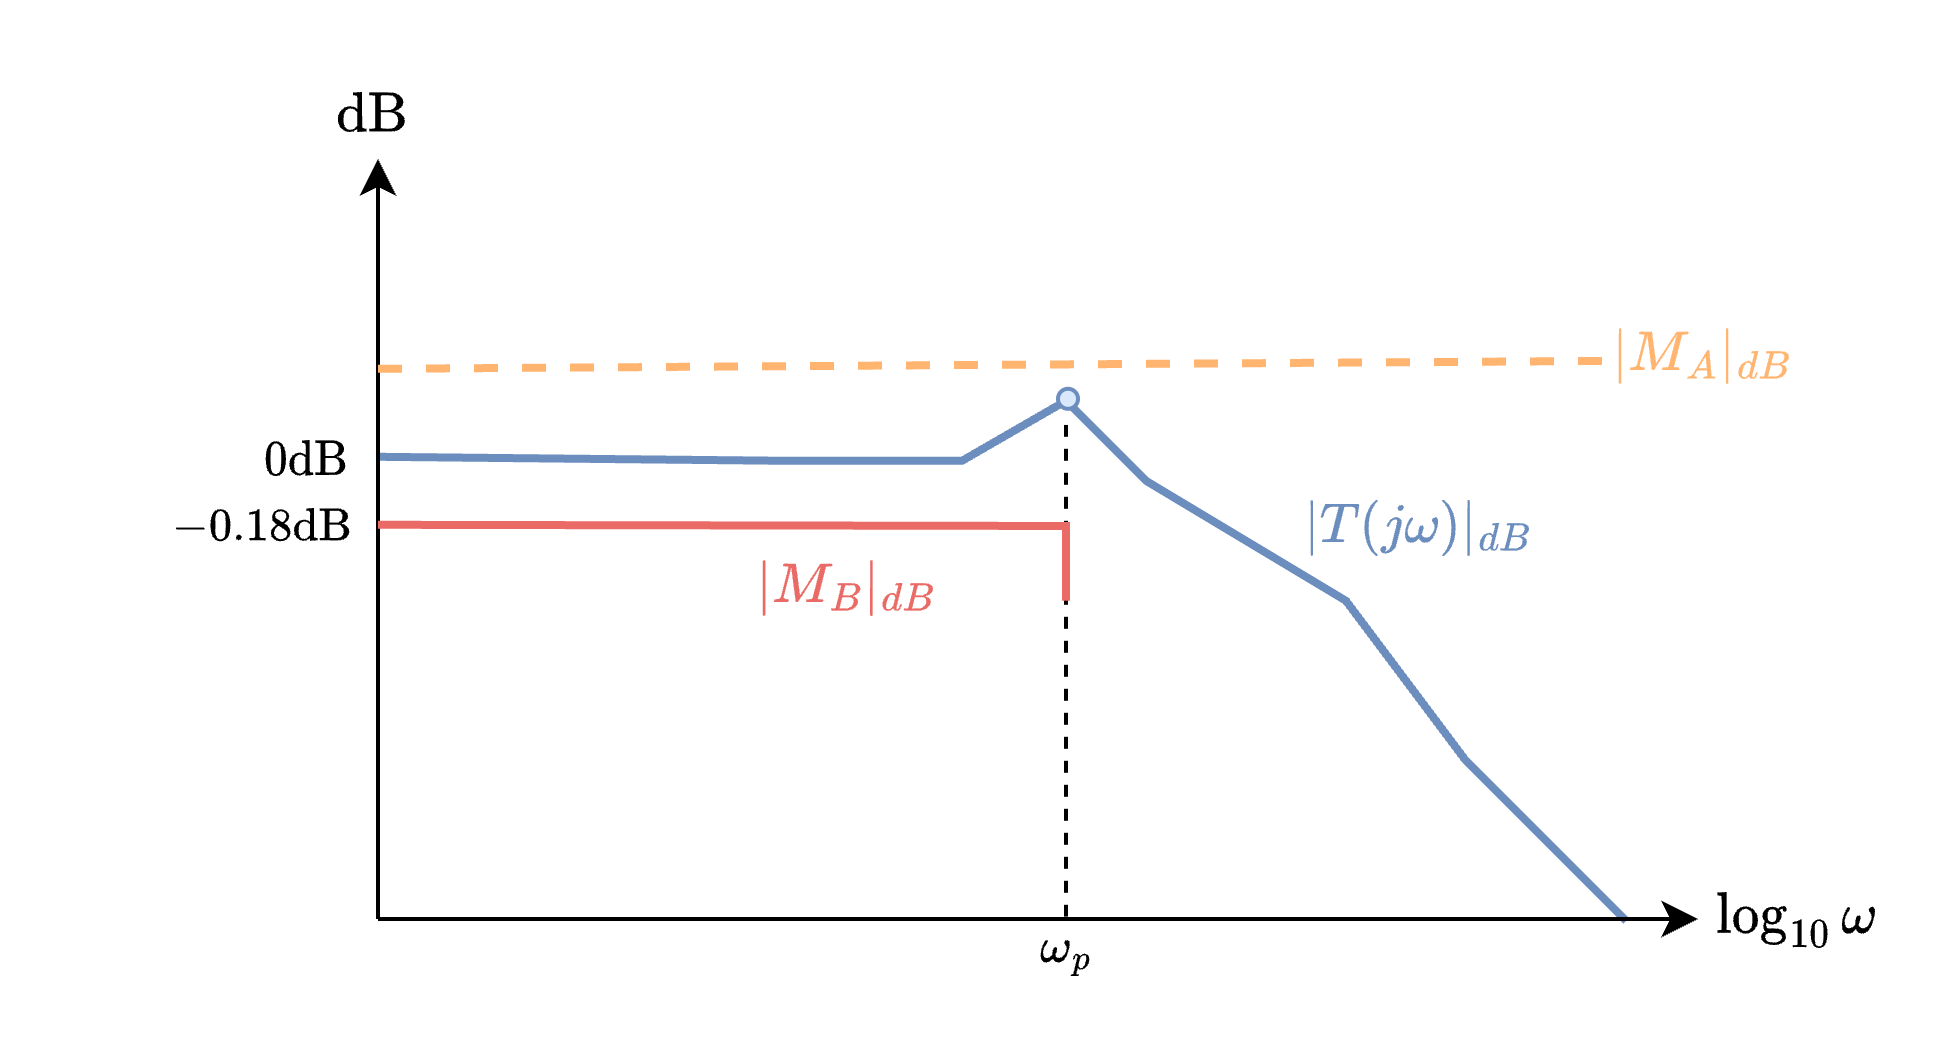

**Figure 11.6**: Simplified *stay-above* and *stay-below* bounds for the magnitude response of $T(j\omega)$.

With reference to Figure 11.6, *stay-below bound *$M_A$ is determined from the percentage overshoot specification and is considered for all frequencies. *Stay-above *bound $M_B$ is determined from the settling time constraint and enforces the appropriate closed-loop bandwidth of the complementary sensitivity function. An appropriate means of doing this is by placing a $-0.18$ dB ($0.98$ in arithmetic units)  *stay-above *bound that is applicable for $\omega\in\left[0,\omega_p\right]$. 

Note that $M_B$ is only considered for $\omega\leq \omega_p$, where $\omega_p=\omega_n\sqrt{1-2\zeta^2}$ is the peak frequency. That is, for frequencies outside of the desired closed-loop bandwidth, $|T(j\omega)|$ can become arbitrarily small. In fact, based our previous discussions, we want $|T(j\omega)|\ll 1$ for frequencies outside of our desired passband. We could add an additional high-frequency bound, $M_{hf}$, to enforce this, as shown in Figure 11.7, but we will keep things simple with the two boundaries (for now). 

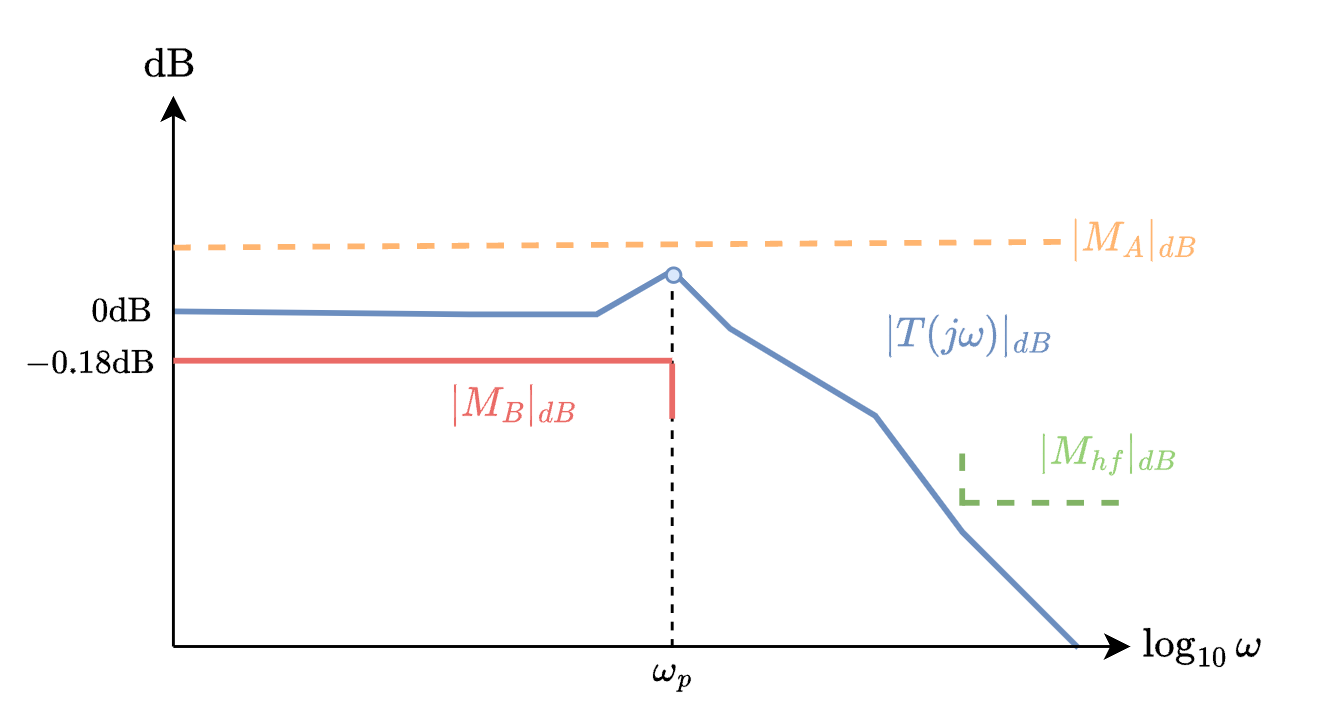

**Figure 11.7**: Simplified *stay-above* and *stay-below* bounds for the magnitude response of $T(j\omega)$, including high-frequency *stay-below *bound.

It is important to note that the approach above does not cater directly for the steady-state error specification. Based on the diagram above, there is a non-zero tolerance for the DC gain of $T(j\omega)$. If a steady-state error specification is additionally given, then we must use our understanding of final-value theorem and type numbers to ensure the correct steady-state behaviour.

The all-frequency *stay-below *bound is calculated using

$M_A=\frac{1}{2\zeta\sqrt{1-\zeta^2}}$,

which we previously determined as the peak magnitude response of a second-order low-pass filter. If a percentage overshoot specification is given, we can use

$\zeta=\frac{-\ln(\%OS/100)}{\sqrt{\pi^2+\ln^2(\%OS/100)}$,

and then substitute the resulting $\zeta$ into the previous equation to determine $M_A$.

$M_B$ is generally set to $0.98$, or $-0.18$ dB in logarithmic units, based on the definition of closed-loop bandwidth, but importantly, we will only consider the $M_B$ bound up until the peak frequency $\omega_p$ of $M_A(j\omega)$. 

We can determine $\omega_p$ using


$$\omega_p=\omega_n\sqrt{1-2\zeta^2},$$


where $\zeta$ has been calculated above. The natural frequency, $\omega_n$, can then be determined based on


$$\omega_n=\frac{4}{\zeta T_s},$$


where $T_s$ is a specified $2\%$ settling time requirement.

#### Example

*Determine the simplified above and below tracking bounds of a 2nd-order system with a settling time of 5 seconds and percentage overshoot of *$25$*%.*

Using the relevant formulas, we can determine the required damping ratio as

$\zeta=\frac{-\ln(\%OS/100)}{\sqrt{\pi^2+\ln^2(\%OS/100)}}=0.40$,

which we use to determine the peak magnitude response:

$M_A=\frac{1}{2\zeta\sqrt{1-\zeta^2}}=1.35$.

The natural frequency corresponding to the determined damping ratio of $\zeta=0.4$ and desired settling time of $T_s=5$ seconds is

$\omega_n=\frac{4}{\zeta T_s}=1.9816$ rad/s,

which allows us to determine the peak frequency as

$\omega_p=\omega_n\sqrt{1-2\zeta^2}=1.6269$ rad/s.

The code below generates the Bode magnitude response of $M_R(j\omega)$, as well as the corresponding simplified *stay-below* and *stay-above* bounds, respectively.

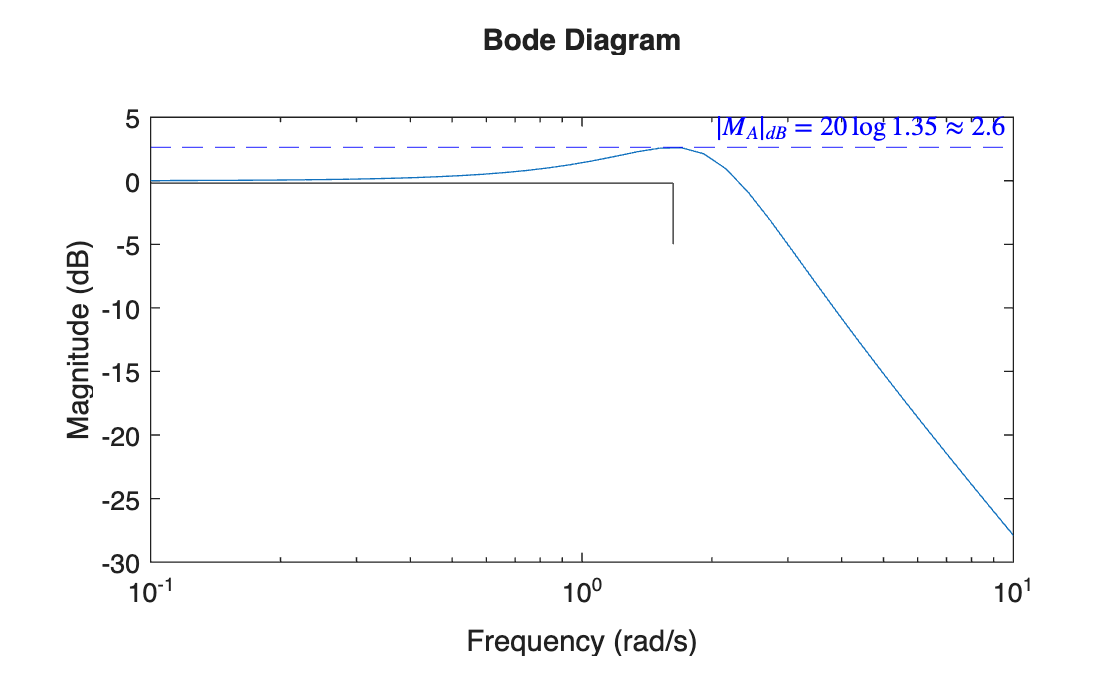

clear
s = tf('s');

%specifications
OS = 25;
Ts = 5;

%stay-below bound
zeta = -log(OS/100)/sqrt( pi^2+log(OS/100)^2);
wn = 4/zeta/Ts;
Ma = 1/( 2*zeta*sqrt(1-zeta^2));


%stay-above bound
wn = 4/zeta/Ts;
wp = wn*sqrt( 1-2*zeta^2 );

%reference tracking model
Mr = wn^2/( s^2+2*zeta*wn*s+wn^2);

%plotting
figure, hold on
bodemag(Mr,{0.1,10})

yline(20*log10(Ma),'--b',['$|M_A|_{dB}=20\log$', num2str(Ma,3),'$\approx$',num2str(20*log10(Ma),2)],'Interpreter','latex')
line([1e-2 wp],[-0.18 -0.18])
line([wp wp],[-0.18 -5])
text(.05,-6,'$|M_B|_{dB}=-3$ dB, $\omega\leq \omega_0$','Interpreter','latex','Color','red')

### 11.5.2 Tracking bounds in the log-polar plane

Once $M_A$ and $M_B$ have been determined, we can then represent these constraints in the log-polar plane. We do this because we then have a clear relationship between $L(s)$, which we will be able shape via $G(s)$, whilst also being able to assess the adherence to the closed-loop specifications.

The code below generates the two boundaries, where the region enclosed by the blue dotted line represents a *stay-out *region for $|T(j\omega)|\leq M_A$, and the region enclosed by the green solid line represents the *stay-out *region for $|T(j\omega)|\geq M_B$.

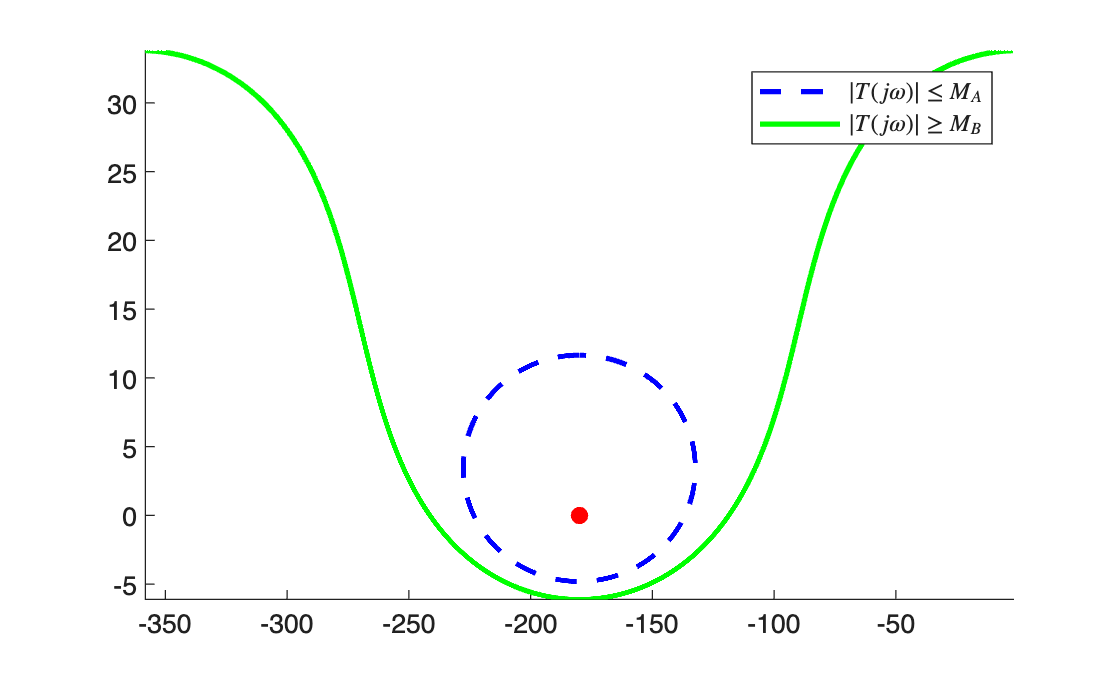

clear

Ma = 1.3537; %calculated in previous code block
Mb = 0.98; %standard value used as a rule of thumb

figure, hold on

M = [Ma Mb];
for k = 1:2
    phi = linspace(0,2*pi,1e4);
    c = -1;
    r = 1/M(k);
    K = c + r*exp(1i*phi);

    mag_K = 20*log10( abs(K) );
    phi_K = angle( K )*180/pi;
    for i=1:length(phi_K)
        if( phi_K(i) > 0), phi_K(i) = phi_K(i)-360; end
    end

    if( k==1 )
        plot( phi_K(2:end-1),-mag_K(2:end-1),'--b',LineWidth=2 )
    else
        plot( phi_K(2:end-1),-mag_K(2:end-1),'-g',LineWidth=2 )
    end
end
plot(-180,0,'ro',MarkerFaceColor='r')
legend('$|T(j\omega)|\leq M_A$','$|T(j\omega)|\geq M_B$','Interpreter','latex')
% grid on
axis tight

% ngrid

In order to satisfy the simplified bounds of

$M_B\leq|T(j\omega)|\leq M_A$,

$L(j\omega)$ must lie outside both regions in the log-polar plane, for their frequencies of interest. As previously mentioned, we consider all frequencies for $|T(j\omega)|\leq M_A$, whereas we only consider frequencies up to the desired closed-loop bandwidth frequency, $\omega_0$, for $M_B\leq|T(j\omega)|$. In other words, $L(j\omega)$ must not enter the region enclosed by the blue dotted line for *any* frequencies, and simultaneously, $L(j\omega)$ must stay outside the region enclosed by the green solid line for frequencies $\omega\leq\omega_p$. It is important to emphasize that these simplified tracking boundaries does not guarantee that the original time-domain specifications will be adhered to. As such, it is good practice to check the behaviour of the relevant output response (e.g. step response) to ensure that our interpretation in the frequency domain matches that of the time-domain. 

#### Example

*Using the log-polar plane, determine whether *$L(s)=\frac{5}{s(s+2)$*, when placed in a unity-feedback loop, will satisfy the closed-loop second-order specifications of a settling time of 5 seconds, percentage overshoot of *$25$*%, zero steady-state error for reference step inputs.*

$L(s)$ is Type-1, so we can be certain that we can achieve zero steady-state error for reference step signals, as the position error constant is

$K_p=\lim_{s\rightarrow 0}L(s)=\infty$.

The other specifications match the previous examples, so we have already determined $M_A$, $M_B$, and $\omega_p$ as

$M_A=1.35$,


$$M_B=0.98,$$


$\omega_p=1.13$ rad/s.

The code below generates the design boundaries in the log-polar plane and also plots the frequency response locus of $L(j\omega)$. Frequency point $\omega=\omega_p$ is also highlighted on the $L(j\omega)$ locus, as we require all frequencies up to $\omega_p$ to be outside (effectively above) the enclosed green region.

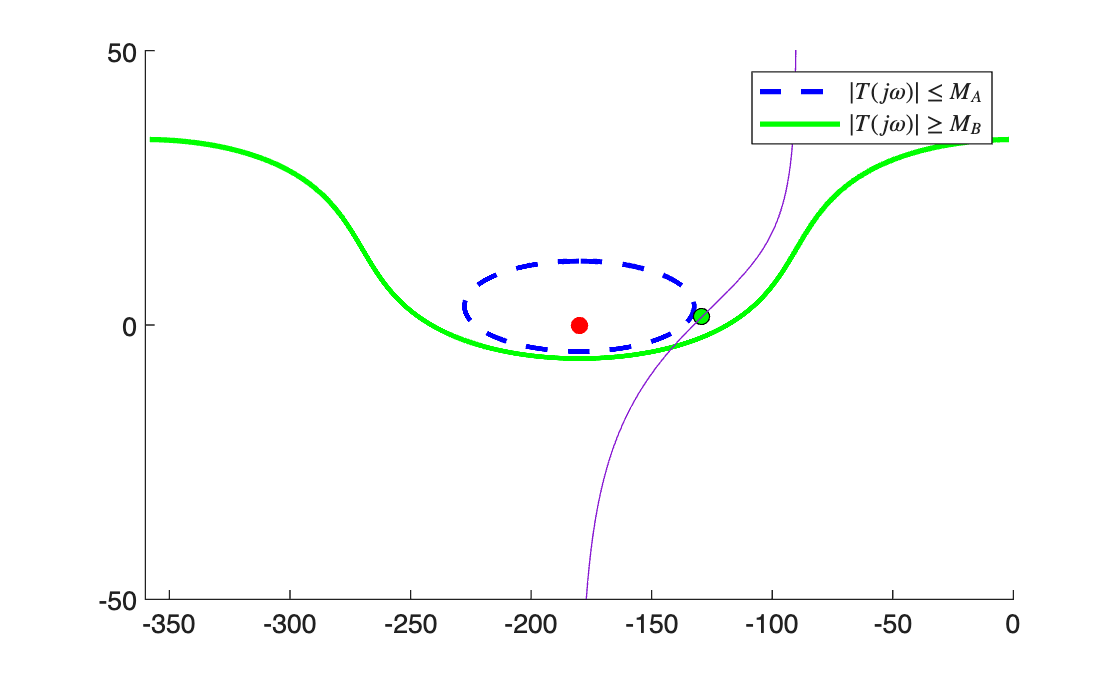

clear
s = tf('s');

L = 5/s/(s+2);

OS = 25;
Ts = 5;

zeta = -log(OS/100)/sqrt( pi^2+log(OS/100)^2);
wn = 4/zeta/Ts;
wp = wn*sqrt( 1-2*zeta^2 );

Ma = 1/( 2*zeta*sqrt(1-zeta^2));
Mb = 0.98;


figure, hold on

M = [Ma Mb];
for k = 1:2
    phi = linspace(0,2*pi,1e4);
    c = -1;
    r = 1/M(k);
    K = c + r*exp(1i*phi);

    mag_K = 20*log10( abs(K) );
    phi_K = angle( K )*180/pi;
    for i=1:length(phi_K)
        if( phi_K(i) > 0), phi_K(i) = phi_K(i)-360; end
    end

    if( k==1 )
        plot( phi_K(2:end-1),-mag_K(2:end-1),'--b',LineWidth=2 )
    else
        plot( phi_K(2:end-1),-mag_K(2:end-1),'-g',LineWidth=2 )
        Lw = squeeze( freqresp(L,wp) );

        plot(angle(Lw)*180/pi,20*log10(abs(Lw)),'go',MarkerFaceColor='g',MarkerEdgeColor='k')
    end
end
[magL,phiL] = nichols(L,{1e-3,1e3});
plot(squeeze(phiL),squeeze(20*log10(magL)))

plot(-180,0,'ro',MarkerFaceColor='r')
legend('$|T(j\omega)|\leq M_A$','$|T(j\omega)|\geq M_B$','Interpreter','latex')
xlim([-360,0]),ylim([-50,50])

Using the desired $M_A$, $M_B$, and $\omega_p$ values shows that $L(s)$ does adhere to the design constraints, which means that we have potentially met the original time-domain specifications of a settling time of 5 seconds and percentage overshoot of $25$%. We can verify this using a step response, as generated from the code below.

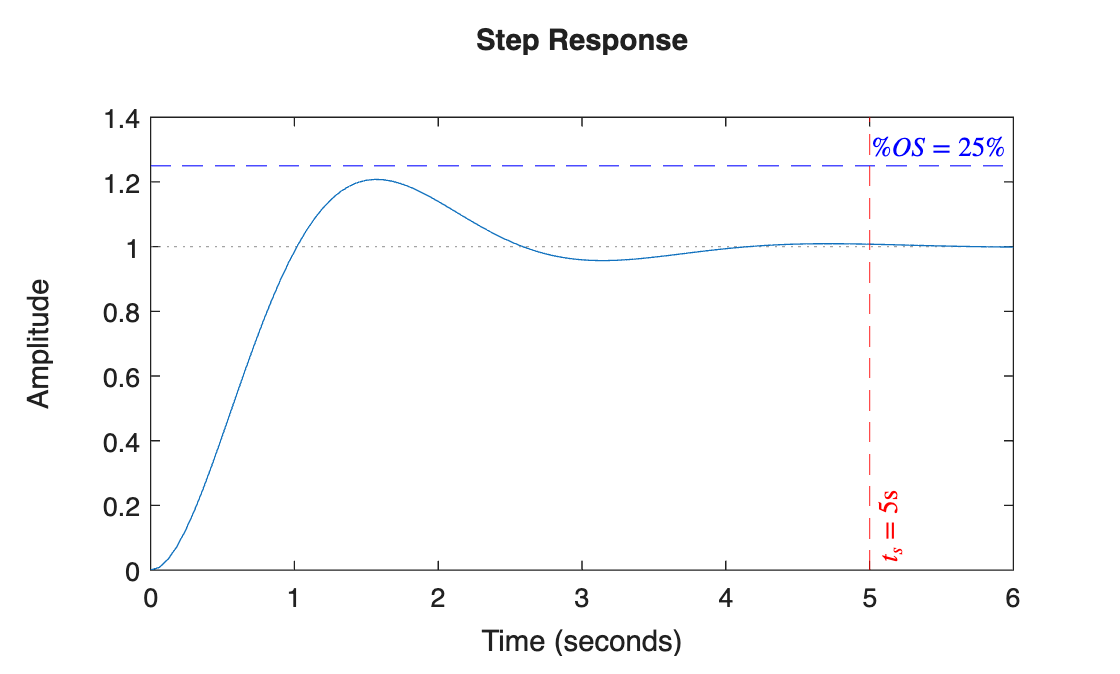

T = feedback(L,1);
figure, hold on
step(T,6)
yline(1.25,'--b','$\% OS=25\%$','Interpreter','latex')
xline(5,'--r','$t_s=5$s','Interpreter','latex','LabelVerticalAlignment','bottom')
ylim([0 1.4])

The step response shows that both the settling time and overshoot specifications have been met. 

It is easy to show that if we instead considered $L(s)=\frac{10}{s(s+2)$, then we would not meet the design constraints in the log-polar plane, as well as the original time-domain constraints. A comparison of $L_1(s)=\frac{5}{s(s+2)}$ and $L_2(s)=\frac{10}{s(s+2)}=2L_1(s)$ is shown using the code below.

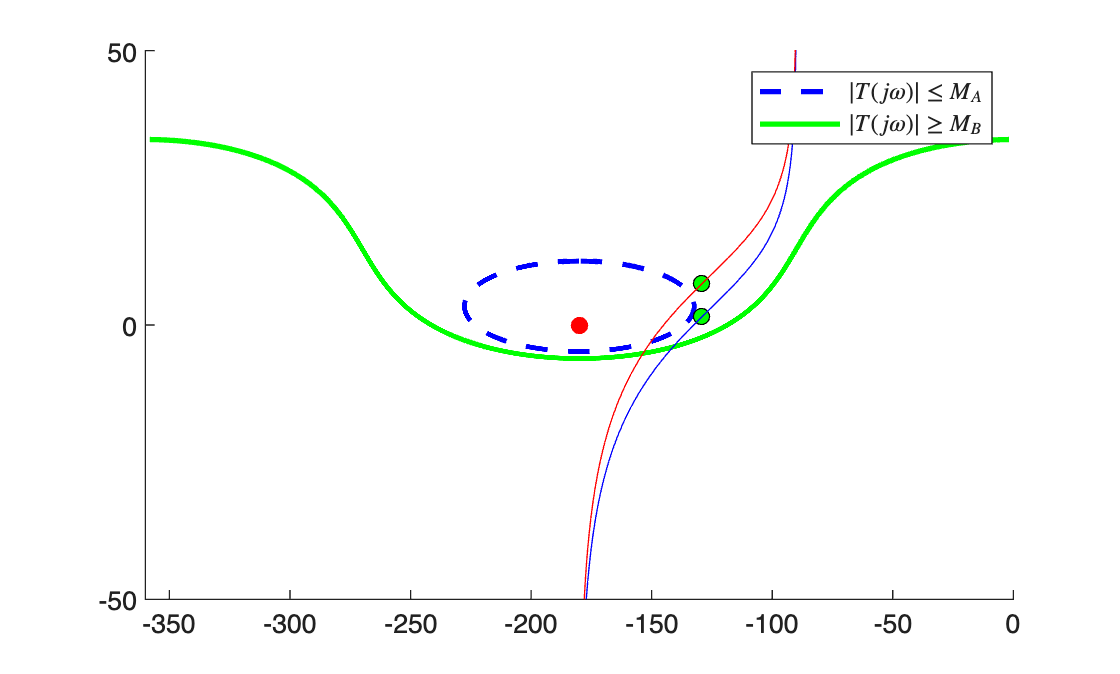

clear
s = tf('s');

L1 = 5/s/(s+2);
L2 = 10/s/(s+2);

OS = 25;
Ts = 5;

zeta = -log(OS/100)/sqrt( pi^2+log(OS/100)^2);
wn = 4/zeta/Ts;
wp = wn*sqrt( 1-2*zeta^2 );

Ma = 1/( 2*zeta*sqrt(1-zeta^2));
Mb = 0.98;


figure, hold on

M = [Ma Mb];
for k = 1:2
    phi = linspace(0,2*pi,1e4);
    c = -1;
    r = 1/M(k);
    K = c + r*exp(1i*phi);

    mag_K = 20*log10( abs(K) );
    phi_K = angle( K )*180/pi;
    for i=1:length(phi_K)
        if( phi_K(i) > 0), phi_K(i) = phi_K(i)-360; end
    end

    if( k==1 )
        plot( phi_K(2:end-1),-mag_K(2:end-1),'--b',LineWidth=2 )
    else
        plot( phi_K(2:end-1),-mag_K(2:end-1),'-g',LineWidth=2 )
        Lw1 = squeeze( freqresp(L1,wp) );
        Lw2 = squeeze( freqresp(L2,wp) );

        plot(angle(Lw1)*180/pi,20*log10(abs(Lw1)),'go',MarkerFaceColor='g',MarkerEdgeColor='k')
        plot(angle(Lw2)*180/pi,20*log10(abs(Lw2)),'go',MarkerFaceColor='g',MarkerEdgeColor='k')
    end
end
[magL1,phiL1] = nichols(L1,{1e-3,1e3});
plot(squeeze(phiL1),squeeze(20*log10(magL1)),'b')
[magL2,phiL2] = nichols(L2,{1e-3,1e3});
plot(squeeze(phiL2),squeeze(20*log10(magL2)),'r')

plot(-180,0,'ro',MarkerFaceColor='r')
legend('$|T(j\omega)|\leq M_A$','$|T(j\omega)|\geq M_B$','Interpreter','latex')
xlim([-360,0]),ylim([-50,50])

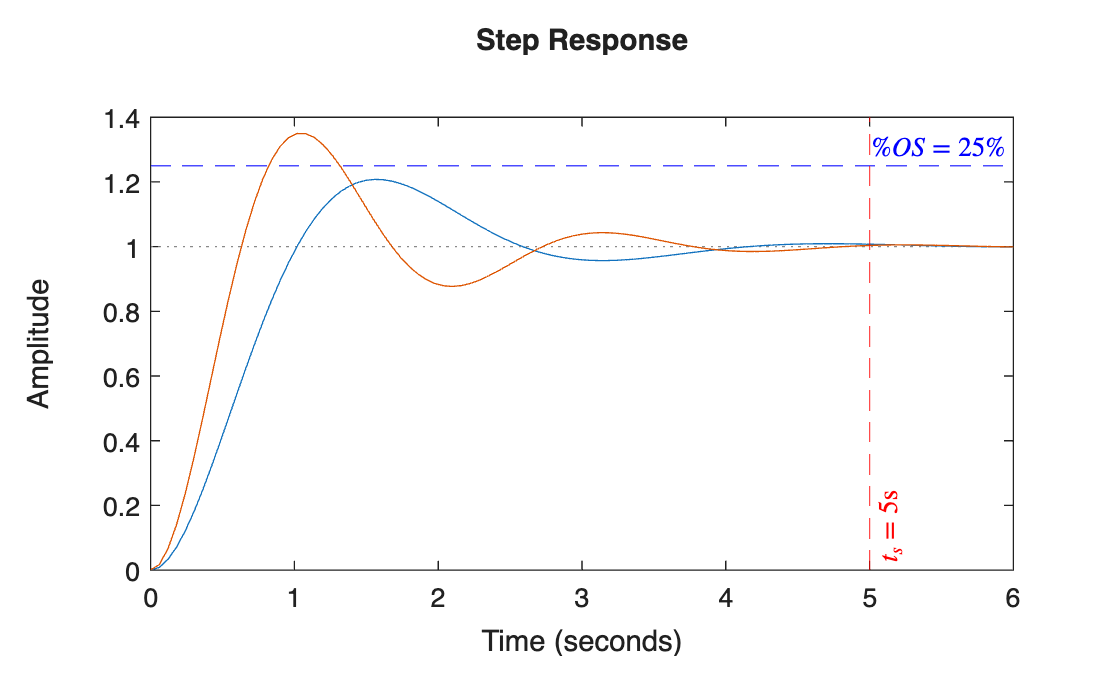

%
T1 = feedback(L1,1);
T2 = feedback(L2,1);
figure, hold on
step(T1,6),step(T2,6)
yline(1.25,'--b','$\% OS=25\%$','Interpreter','latex')
xline(5,'--r','$t_s=5$s','Interpreter','latex','LabelVerticalAlignment','bottom')
ylim([0 1.4])

As shown in the log-polar plot and step response, $L_2(s)$ violates the percentage overshoot boundary. 

Now that we have a way to represent closed-loop design constraints on $L(s)$, we can begin to look at how to shape $L(s)$ via $G(s)$ in order to meet the required closed-loop tracking behaviour. We will cover this in the following chapter.